# Entropy From AE Signals

clear
clc

Type = 'DPMS0T' ;
Materiau = '7075';
Eprouvette ='3';
Numero = '1';
channel = "2";
thresholdDB = 40;
addpath('/home/tdelaselle/Documents/Codes/Codes persos Matlab/Fonctions');
repertoire_brute = acces_donnees_brutes();
dossier = strcat(repertoire_brute,'/',Type,'/',Materiau,'/',Eprouvette,'.',Numero,'/','EA','/','waveforms');
addpath(dossier);
channel1 = dir(strcat(dossier,'/*_1_*.txt'));
channel2 = dir(strcat(dossier,'/*_2_*.txt'));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);

% Nombre de valeurs
sizeOfWaveform = 5134;  
% sizeOfWaveform = 2048 ; 
freq = 5;

% Smallest division is 20V/65536 = 0.00030518, so choosing 0.001
binwidth = 0.001;
% binwidth = 0.0010;

        (valeur conseillée : 0.001)

% Test name, label, number of waveform files, specified threshold
numberOfFiles = size(channel2,1);
if channel == "1"
    numberOfFiles = size(channel1,1);
end
numberOfFiles = 198;
%Text files
fileType = '.txt';
% Preamp gain in dB
preamp = 40;
%Threshold gain in dB, equation from AEWin manual
thresholdVolt = (10^((thresholdDB+preamp)./20))*(10^-6);
% Preallocate
entropy1 = zeros(numberOfFiles,2);
entropy2 = zeros(numberOfFiles,2);
entropy3 = zeros(numberOfFiles,2);
maximum = zeros(numberOfFiles,2);
countsFromWaveforms = zeros(numberOfFiles,2);
time = zeros(1,numberOfFiles);
mat1 = zeros(sizeOfWaveform,1);

% Histogram bin edges and middle points for temporally weighted entropy
edges = -10:0.001:10;
mid = -10+0.0005:0.001:10-0.0005;
mat2 = zeros(sizeOfWaveform,1);
allProb = zeros(sizeOfWaveform,length(mid));
weightedProb = zeros(numberOfFiles,length(mid));

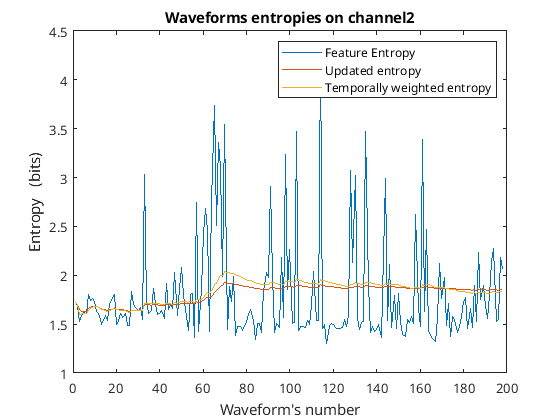

%% 3 different entropies as new signals are received
for i = 1:numberOfFiles
    
    %%% Loading data from iterative text files
    % Indexes through waveform numbers
    fileIndex = num2str(i);
    % Entire file name
    fileName = strcat(Naming,'_',channel,'_',fileIndex,fileType);
    % Open file
    fileID = fopen(fileName);
    % Imports file to strings
    wholeWaveform = textscan(fileID,'%s','Delimiter','\n');
    timeWaveform = wholeWaveform{1,1}(11); 
    workForTime= sscanf(timeWaveform{1,1},'%s%s%s%f');
    % Signal arrival time
    time(i) = workForTime(12);  % Position temporelle de la wf
    % AE signal voltage data in strings
    waveformData = wholeWaveform{1,1}(13:end);
    
    % AE signal voltage data in values
    for k = 1:sizeOfWaveform
        mat1(k) = sscanf(waveformData{k}, '%*f, %f'); % On supprime la premiere colonne ('%*f,')
    end
    %Close file
    fclose(fileID);
    %%% Indexing
    entropy1(i,1) = i;
    entropy2(i,1) = i;
    entropy3(i,1) = i;
    maximum(i,1) = i;
    countsFromWaveforms(i,1) = i;
    % Maximum voltage value from AE signal
    maximum(i,2) = max(mat1);
    % Counts directly from raw AE signal
    countsFromWaveforms(i,2) = sum(mat1>thresholdVolt);
    %%% 1) Feature Entropy from each waveform
    % Finding probability distribution with auto binning rules
    [prob1, Edge1] = histcounts(mat1,'BinWidth',binwidth,'Normalization','probability');
    % Preallocate
    S1 = zeros(length(prob1),1);
    for q = 1:length(prob1)
        % Calculate individual terms of Shannon's equation for each
        % possible outcome (in this case, histogram bar)
        if prob1(q)>0
            S1(q) = -prob1(q)*log2(prob1(q));
        end
    end
    % Sum terms to get entropy
    entropy1(i,2) = sum(S1);
    %%% 2) Updated entropy from waveforms
    % Want histogram to be mobile with constant bin width. This means the
    % waveforms need to be put into one array and then passed to
    % histcounts.
    % Making one very large array with all waveforms together
    mat2(sizeOfWaveform*(i-1)+1:sizeOfWaveform*i) = mat1;
    % Finding probability distribution of all received voltage values
    [prob2, Edge2] =histcounts(mat2,'BinWidth',binwidth,'Normalization','probability');
    % Preallocate
    S2 = zeros(length(prob2),1);
    for j = 1:length(prob2)
        % Calculate individual terms of Shannon's equation for each
        % possible outcome (in this case, histogram bar)
        if prob2(j)>0
            S2(j) = -prob2(j)*log2(prob2(j));
        end
    end
    % Sum terms to get entropy
    entropy2(i,2) = sum(S2);
    %%% 3) Temporally weighted entropy from waveforms
    % Want to devise a way so that the probability distribution of the
    % current signal has a greater effect on the system probability
    % distribution than the previous signals
    % Making one very large array with all waveforms together
    [prob, edge1] = histcounts(mat1,'BinEdges',edges,'Normalization','probability');
    allProb(i,:) = prob; %
    % Get the current vector of arrival times
    current = time(1:i);
    % Get the temporal linear weights
    weights = current./sum(current);
    % Multiply probably distributions by weights
    weightedProb(i,:) = weights*allProb(1:i,:);
    % Preallocate
    S3 = zeros(length(weightedProb(i,:)),1);
    for j = 1:length(weightedProb(i,:))
        % Calculate individual terms of Shannon's equation for each
        % possible outcome (in this case, histogram bar)
        if weightedProb(i,j)>0
            S3(j) = -weightedProb(i,j)*log2(weightedProb(i,j));
        end
    end
    % Sum terms to get entropy
    entropy3(i,2) = sum(S3);
    % Checking all pdf's always sum to 1
    checkFor1_1 = sum(prob1);
    if checkFor1_1 > 1.0001 || checkFor1_1 < 0.9999
        str = sprintf('ERROR: PDF for %d does not sum to 1', i);
    end
    checkFor1_2 = sum(prob2);
    if checkFor1_2 > 1.0001 || checkFor1_2 < 0.9999
        str = sprintf('ERROR: PDF for %d does not sum to 1', i);
    end
    checkFor1_3 = sum(allProb(i,:));
    if checkFor1_3 > 1.0001 || checkFor1_3 < 0.9999
        str = sprintf('ERROR: PDF for %d does not sum to 1', i);
    end
end
plot(entropy1(:,1),entropy1(:,2));
hold on 
plot(entropy2(:,1),entropy2(:,2));
plot(entropy3(:,1),entropy3(:,2));
hold off
legend('Feature Entropy','Updated entropy','Temporally weighted entropy');
title(strcat('Waveforms entropies on channel ',channel));
xlabel("Waveform's number");
ylabel("Entropy   (bits)");

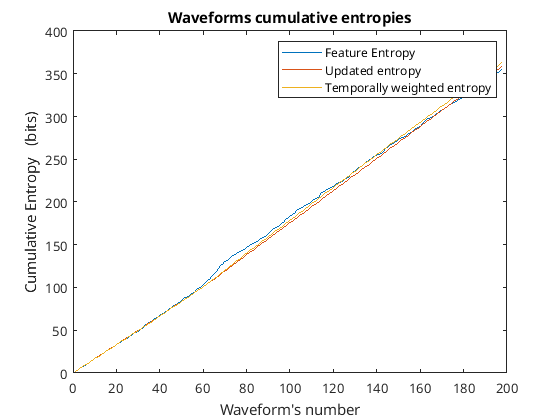

% Cumulative entropies
CumEntrop1 = entropy1;
CumEntrop2 = entropy2;
CumEntrop3 = entropy3;
for i=2:numberOfFiles
    CumEntrop1(i,2) = CumEntrop1(i-1,2)+CumEntrop1(i,2);
    CumEntrop2(i,2) = CumEntrop2(i-1,2)+CumEntrop2(i,2);
    CumEntrop3(i,2) = CumEntrop3(i-1,2)+CumEntrop3(i,2);
end
plot(CumEntrop1(:,1),CumEntrop1(:,2));
hold on 
plot(CumEntrop2(:,1),CumEntrop2(:,2));
plot(CumEntrop3(:,1),CumEntrop3(:,2));
hold off
legend('Feature Entropy','Updated entropy','Temporally weighted entropy');
title('Waveforms cumulative entropies');
xlabel("Waveform's number");
ylabel("Cumulative Entropy   (bits)");

figure;

% Création d'une table et enregistrement .mat
ENT = table(entropy1(:,1),entropy1(:,2),CumEntrop1(:,2),entropy2(:,2),CumEntrop2(:,2),entropy3(:,2),CumEntrop3(:,2));
ENT.Properties.VariableNames = {'Nbre WF' 'Feature' 'Cumu feature' 'Updated' 'Cumu updated' 'Temporally weighted' 'Cumu Temporally weighted'}

ENT = 198×7 table
    Nbre WF    Feature    Cumu feature    Updated    Cumu updated    Temporally weighted    Cumu Temporally weighted
    _______    _______    ____________    _______    ____________    ___________________    ________________________

       1       1.7252        1.7252       1.7252        1.7252             1.7252                    1.7252         
       2       1.6812        3.4064       1.7044        3.4296             1.7044                    3.4296         
       3       1.5223        4.9287       1.6471        5.0768             1.6033                    5.0329         
       4       1.5838        6.5125       1.6333        6.7101             1.5979                    6.6308         
       5       1.6152        8.1277      

enregistrement =  false;
if enregistrement == 1
    repertoire_traitees = acces_donnees_traitees();
    load(strcat(repertoire_traitees,Type,'/',Materiau,'/',Naming,'.mat'));
    % ATTENTION : bien vérifier que l'on ne supprime rien du fichier raffiné
    save(strcat(repertoire_traitees,Type,'/',Materiau,'/',Naming,'.mat'),'HDD','TDD','WF','CUMU','ENT');    
end